## Laborator 1

### Aplicatii

**Problema 1: Sa se scrie formula lui Maclaurin pt functia **$f : \left[-a, \infty \right] \rightarrow \mathbb{R}, f(x)= \sqrt{a + x}, a \gt 0$

syms a x
assume(a > 0);
f = (1 + x/a) ^ (1/2);
a ^ (1/2) * taylor(f, x, 'Order', 8)

$$ans = \sqrt{a}\,\left(\frac{x}{2\,a}-\frac{x^{2}}{8\,a^{2}}+\frac{x^{3}}{16\,a^{3}}-\frac{5\,x^{4}}{128\,a^{4}}+\frac{7\,x^{5}}{256\,a^{5}}-\frac{21\,x^{6}}{1024\,a^{6}}+\frac{33\,x^{7}}{2048\,a^{7}}+1\right)$$

### Problema 2

sympref('PolynomialDisplayStyle','ascend');
f = exp(x);
et = taylor(f, x, 0, 'Order', 7)

$$et = 1+x+\frac{x^{2}}{2}+\frac{x^{3}}{6}+\frac{x^{4}}{24}+\frac{x^{5}}{120}+\frac{x^{6}}{720}$$

for n = 3:8
    disp([n, 3/factorial(n+1)])
end

    3.0000    0.1250

    4.0000    0.0250

    5.0000    0.0042

    6.0000    0.0006

    7.0000    0.0001

    8.0000    0.0000



ap = subs(et, x, 1)

$$ap = \frac{1957}{720}$$

### Problema 3

f(x) = (1+x)^(1/3);
10*taylor(f(x), x, 0)

$$ans = 10+\frac{10\,x}{3}-\frac{10\,x^{2}}{9}+\frac{50\,x^{3}}{81}-\frac{100\,x^{4}}{243}+\frac{220\,x^{5}}{729}$$

syms n
R=abs(nchoosek(sym('1/3'), n)*10^(-3*n));
double(subs(R, n, 3))

ans = 6.1728e-11

double(subs(R, n, 4))

ans = 4.1152e-14

format long
syms ty
ty=10*taylor(f(x), x, 0, 'Order', 4);
double(subs(ty, x, -1e-3))

ans =    9.996665554938271


### Problema 5

clear
format long
syms x
f = log(1 + x);

Folosind primii 8 termeni

et = taylor(f, x, 0, 'Order', 8)

$$et = x-\frac{x^{2}}{2}+\frac{x^{3}}{3}-\frac{x^{4}}{4}+\frac{x^{5}}{5}-\frac{x^{6}}{6}+\frac{x^{7}}{7}$$

double(subs(et, x, 1))

ans =    0.759523809523809


Pt a obtine ln2 cu 5 zecimale corecte

Cunoastem serie alternanta => Restul este mai mica decat ultimul termen neglijat: $\left|R_{n+1}\right|  \lt \left| \left(-1\right)\frac{x^{n+1}}{n+1}\right|
 $ 

Cum lucram pt x = 1, cu 5 zecimale corecte => $\left| R_{n+1} \right| \lt \left| \frac{1}{n+1} \right| < \frac{1}{10^5}$

Vom lua $n + 1 \gt 10^5 \rightarrow n \gt 10^5 - 1$

fprintf('1/(10^n) = %.15f\n', 1/100000);

1/(10^n) = 0.000010000000000


for n = 100000  : 100010
    fprintf('n = %d, 1/(n+1) = %.15f\n', n, 1/(n+1));
    %disp([n, 1/(n+1)])
end

n = 100000, 1/(n+1) = 0.000009999900001
n = 100001, 1/(n+1) = 0.000009999800004
n = 100002, 1/(n+1) = 0.000009999700009
n = 100003, 1/(n+1) = 0.000009999600016
n = 100004, 1/(n+1) = 0.000009999500025
n = 100005, 1/(n+1) = 0.000009999400036
n = 100006, 1/(n+1) = 0.000009999300049
n = 100007, 1/(n+1) = 0.000009999200064
n = 100008, 1/(n+1) = 0.000009999100081
n = 100009, 1/(n+1) = 0.000009999000100
n = 100010, 1/(n+1) = 0.000009998900121


=> $n = 10^5$ e de ajuns pt 5 zecimale

et2 = taylor(f, x, 0, 'Order', 100000);
double(subs(et2, x, 1))

ans =    0.693152180584945


log(2)

ans =    0.693147180559945


Pentru $ln \frac{1+x}{1-x}$

Aflam x a.i. $\frac{1+x}{1-x} = 2$

solve((1+x)/(1-x) == 2, x)

$$ans = \frac{1}{3}$$


$$ln\frac{1+x}{1-x} = ln\left(1+x\right) - ln\left(1-x\right)$$


Folosind primii 8 termeni pt ln(2), cu x = 1/3

f = taylor(log(1+x), x, 0, 'Order', 8) - taylor(log(1-x), x, 0, 'Order', 8)

$$f = 2\,x+\frac{2\,x^{3}}{3}+\frac{2\,x^{5}}{5}+\frac{2\,x^{7}}{7}$$

double(subs(f, x, 1/3))

ans =    0.693134757332288


Consideram seria taylor in jurul $ln \frac{1+x}{1-x}$ ca diferenta intre seria taylor in jurul $ln \left(1 + x) 
$ si seria taylor in jurul $ln \left(1 + (-x) \right)
$

Seriile sunt ambele alternante, conform $ln(1+x)
$, deci restul lor va fi mai mic decat ultimul termen neglijat, ca la punctul anterior

Restul diferentei dintre cele 2 serii va fi: $\left| R_{n+1}\left(x\right) - R_{n+1}\left(-x\right) \right| \lt \frac{ \left(\frac{1}{3}\right)^\left(n+1\right) - \left( - \frac{1}{3}\right)^\left(n+1\right)}{\left(n+1\right)} \lt \frac{1}{10^5}$

format long;
syms n
f3 = (((1/3)^(n+1)) - ((-1/3)^(n+1))) / (n+1)

$$f3 = -\frac{{\left(-\frac{1}{3}\right)}^{1+n}-{\left(\frac{1}{3}\right)}^{1+n}}{1+n}$$

fprintf("1/(10^n) = %.15f\n", 1 / 100000);

1/(10^n) = 0.000010000000000


for y=1:12
    fprintf("n = %d, f3(n) = %.15f\n", y, subs(f3, n, y));
    %disp([y, double(subs(f3, n, y))]);
end

n = 1, f3(n) = 0.000000000000000
n = 2, f3(n) = 0.024691358024691
n = 3, f3(n) = 0.000000000000000
n = 4, f3(n) = 0.001646090534979
n = 5, f3(n) = 0.000000000000000
n = 6, f3(n) = 0.000130642105951
n = 7, f3(n) = 0.000000000000000
n = 8, f3(n) = 0.000011290058539
n = 9, f3(n) = 0.000000000000000
n = 10, f3(n) = 0.000001026368958
n = 11, f3(n) = 0.000000000000000
n = 12, f3(n) = 0.000000096496227


Pt n = 10 avem precizia = 5, dar cum se anuleaza din 2 in 2 => 5 termeni (n = 5 sau 10?)

f4 = taylor(log((1+x)/(1-x)), x, 0, 'Order', 10);
double(subs(f4, x, 1/3))

ans =    0.693146047390827


log(2)

ans =    0.693147180559945


### Problema 7 - Aproximare cu serii Maclaurin


$$f(x) \approx T_n(x) = \sum_{i=0}^{n}c_ix^i
\\
c_i = \frac{f^\left(i\right)\left(0\right)}{i!}$$


a) Repr grafic $e^x
$ si comparati cu graficele $T_1f(x),T_2f(x), T_3f(x), T_4f(x),T_5f(x),$

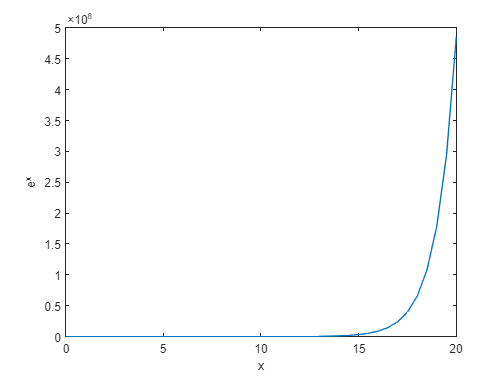

syms x
x_vector = 0:0.5:20;
f = exp(x_vector);
plot(x_vector, f);
xlabel('x');
ylabel('e^x');

Salvez $c_i, i \in [1, 5]$

f_exp = exp(x);
n = 15;
syms x2
x2 = 0:0.5:20;
derivatives = zeros(1, n);
for i = 1:n
    derivative = diff(f_exp, x, i - 1);
    derivative_at_0 = subs(derivative, x, 0);
    derivatives(i) = derivative_at_0 / factorial(i - 1);
end
disp(derivatives);

  Columns 1 through 12

   1.000000000000000   1.000000000000000   0.500000000000000   0.166666666666667   0.041666666666667   0.008333333333333   0.001388888888889   0.000198412698413   0.000024801587302   0.000002755731922   0.000000275573192   0.000000025052108

  Columns 13 through 15

   0.000000002087676   0.000000000160590   0.000000000011471



previous_f = @(x2) derivatives(1) * x2.^0;
f_array = {previous_f(x2)};
for i = 2:n
    derivative_value = derivatives(i - 1);
    new_f = @(x2) previous_f(x2) + derivative_value * x2.^i;
    f_array = [f_array, {new_f}];
    previous_f = new_f;
end

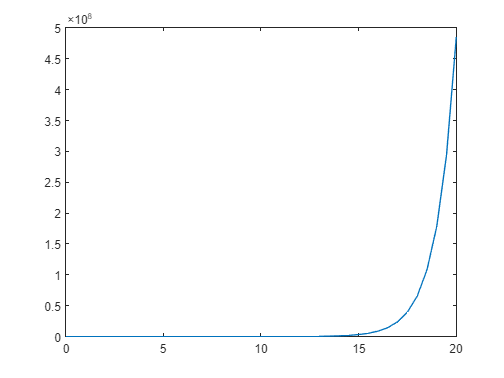

plot(x2, f);

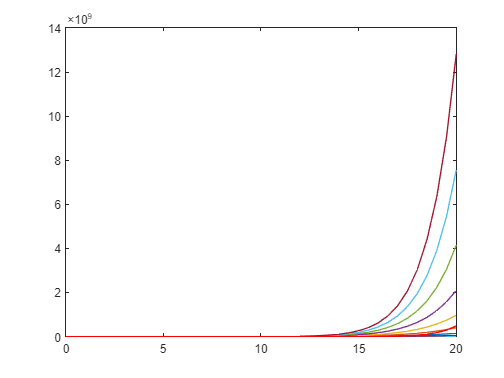

for i = 2:n
    y_values = f_array{i}(x2);
    plot(x2, y_values);
    hold on;
end
plot(x2, f, 'r');
hold off;

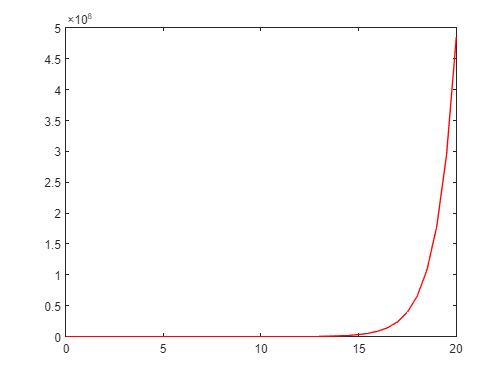

plot(x2, f, 'r');

Pt x - vector de valori din intervalul [0, 20], step = 0.5

Aproximeaza multumitor pe un interval din ce in ce mai mare in jurul originii, dar cresc mult mai repede polinoamele dupa un anumit timp

Pt  n=10, aproximeaza pana pe la x=10

Pt n=15, aproximeaza pana pe la x=13

Pt n=20, aproximeaxa pana pe la x=15

b) pentru g(x) = ln(1+x)

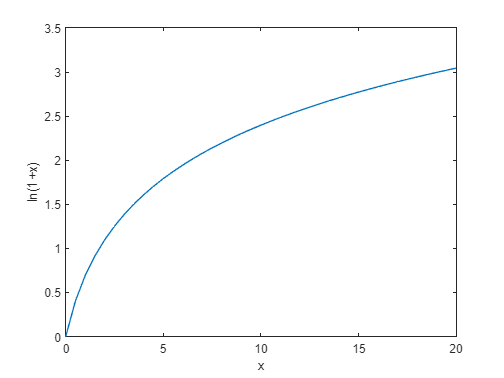

syms x
x_vector = 0:0.5:20;
f = log(1+x_vector);
plot(x_vector, f);
xlabel('x');
ylabel('ln(1+x)');

f_ln = log(1+x);
n = 20;
syms x2
x2 = 0:0.5:20;
derivatives = zeros(1, n);
for i = 1:n
    derivative = diff(f_ln, x, i - 1);
    derivative_at_0 = subs(derivative, x, 0);
    derivatives(i) = derivative_at_0 / factorial(i - 1);
end
disp(derivatives);

  Columns 1 through 12

                   0   1.000000000000000  -0.500000000000000   0.333333333333333  -0.250000000000000   0.200000000000000  -0.166666666666667   0.142857142857143  -0.125000000000000   0.111111111111111  -0.100000000000000   0.090909090909091

  Columns 13 through 20

  -0.083333333333333   0.076923076923077  -0.071428571428571   0.066666666666667  -0.062500000000000   0.058823529411765  -0.055555555555556   0.052631578947368



previous_f = @(x2) derivatives(1) * x2.^0;
f_array = {previous_f(x2)};
for i = 2:n
    derivative_value = derivatives(i - 1);
    new_f = @(x2) previous_f(x2) + derivative_value * x2.^i;
    f_array = [f_array, {new_f}];
    previous_f = new_f;
end


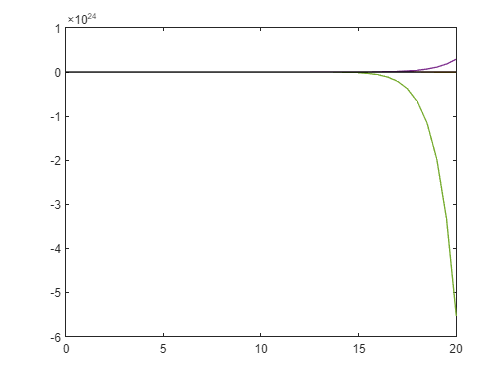

for i = 2:n
    y_values = f_array{i}(x2);
    plot(x2, y_values);
    hold on;
end
plot(x2, f, 'black');
hold off;

Pt x - vector de valori din intervalul [0, 20], step = 0.5

Aproximeaza multumitor pe un interval din ce in ce mai mare in jurul originii, dar se distanteaza mult mai repede polinoamele dupa un anumit timp

Pt  n=10, aproximeaza pana pe la x=13

Pt n=15, aproximeaza pana pe la x=14

Pt n=20, aproximeaxa pana pe la x=16

### Problema 8

b) $f(x) = e^x
$


$$R_{1,1}(x)$$


clear;
syms x
R11 = my_pade(@(x) exp(x), 1, 1, x);
simplifyFraction(R11)

$$ans = -\frac{2+x}{-2+x}$$

pade(exp(x), x, 'Order', [sym(1), sym(1)])

$$ans = -\frac{2+x}{-2+x}$$

x_vec = -1:0.1:1;

#### 
$$R_{2,2}
$$


R22 = my_pade(@(x) exp(x), 2, 2, x);
simplifyFraction(R22)

$$ans = \frac{12+6\,x+x^{2}}{12-6\,x+x^{2}}$$

pade(exp(x), x, 'Order', [sym(2), sym(2)])

$$ans = \frac{12+6\,x+x^{2}}{12-6\,x+x^{2}}$$

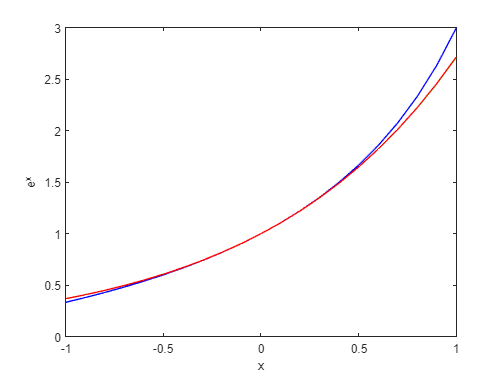

y_R11_exp_value = subs(R11, x, x_vec);
plot(x_vec, y_R11_exp_value,'blue');
hold on;
y_R22_exp_value = subs(R22, x, x_vec);
plot(x_vec, y_R22_exp_value,'green');
y_exp_value = exp(x_vec);
plot(x_vec, y_exp_value, 'red');
hold off;
xlabel('x');
ylabel('e^x');

$R_{2,2} 
$  aproximeaza foarte bine pe $[-1, 1]$ (nici nu se vede). Mai bun decat prin trunchiere

c) $g(x) = ln(1+x)$


$$R_{3,1}
$$


clear;
syms x
R31 = my_pade(@(x) log(1+x), 3, 1, x);
simplifyFraction(R31)

$$ans = \frac{24\,x+6\,x^{2}-x^{3}}{6\,\left(4+3\,x\right)}$$

pade(log(1+x), x, 'Order', [sym(3), sym(1)])

$$ans = \frac{x\,\left(24+6\,x-x^{2}\right)}{6\,\left(4+3\,x\right)}$$

x_vec = -1:0.1:1;

#### 
$$R_{2,2}
$$


R22 = my_pade(@(x) log(1+x), 2, 2, x);
simplifyFraction(R22)

$$ans = \frac{3\,\left(2\,x+x^{2}\right)}{6+6\,x+x^{2}}$$

pade(log(1+x), x, 'Order', [sym(2), sym(2)])

$$ans = \frac{3\,x\,\left(2+x\right)}{6+6\,x+x^{2}}$$

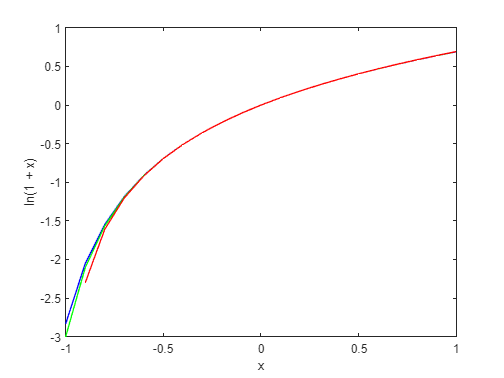

y_R31_exp_value = subs(R31, x, x_vec);
plot(x_vec, y_R31_exp_value,'blue');
hold on;
y_R22_exp_value = subs(R22, x, x_vec);
plot(x_vec, y_R22_exp_value,'green');
y_exp_value = log(1 + x_vec);
plot(x_vec, y_exp_value, 'red');
hold off;
xlabel('x');
ylabel('ln(1 + x)');

Aproximatiile sunt satisfacatoare, mai bune decat prin trunchiere